# **Optimal Policies With Dynamic Programming**

## Gridworld

Tenemos un espacio físico dividido en la forma de una cuadrícula. El agente tiene la tarea de navegar hasta una celda específica a la que se le denomina meta. Las acciones que puede tomar el agente consisten de las diferentes direcciones en las que se puede movilizar el mismo. Los estados consisten de las diferentes posiciones que puede ocupar el agente en la cuadrícula y los estados futuros consisten de las casillas en las que el agente caerá luego de movilizarse. En estados "extremos" (En los bordes de la cuadrícula) el agente vuelve a caer en el mismo estado si la acción conllevara a que el mismo se saliera de la cuadrícula. 

% Dimensiones del grid en el que se desplazará el agente.
AnchoGrid = 10;
AltoGrid = 10;

% Estados
Estados = 1:(AnchoGrid * AltoGrid);
MatrizEstados = reshape(Estados,AltoGrid,AnchoGrid)

MatrizEstados =      1    11    21    31    41    51    61    71    81    91
     2    12    22    32    42    52    62    72    82    92
     3    13    23    33    43    53    63    73    83    93
     4    14    24    34    44    54    64    74    84    94
     5    15    25    35    45    55    65    75    85    95
     6    16    26    36    46    56    66    76    86    96
     7    17    27    37    47    57    67    77    87    97
     8    18    28    38    48    58    68    78    88    98
     9    19    29    39    49    59    69    79    89    99
    10    20    30    40    50    60    70    80    90   100


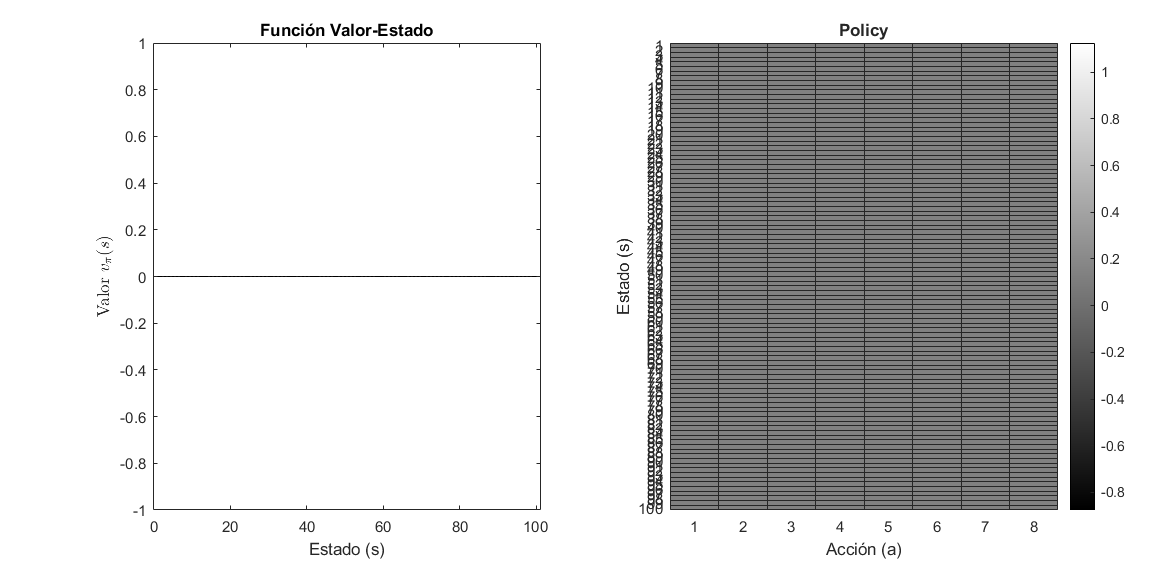

NoEstados = numel(Estados);

% Estados meta donde se acaban los episodios
EstadosMeta = [1]';
EstadosObs = [21 22 23 90 89 99 100]';

% Acciones
% 1: Arriba / 2: Abajo / 3: Izquierda / 4: Derecha
% 5: Arriba-izquierda / 6: Arriba-derecha
% 7: Abajo-izquierda / 8: Abajo-derecha
Direcciones = 8;
Acciones = 1:Direcciones;
NoAcciones = numel(Acciones);

% Policy
% Igual probabilidad de moverse en alguna de las direcciones disponibles.
Policy = ones(NoEstados,NoAcciones) / Direcciones;

% Inicialización de valor de estados
V = zeros(size(Estados));

% Gráfica de la función de valor y la policy
figure(1); clf;
PlotStateSpace(Estados,Acciones,Policy,V);

## Policy Iteration

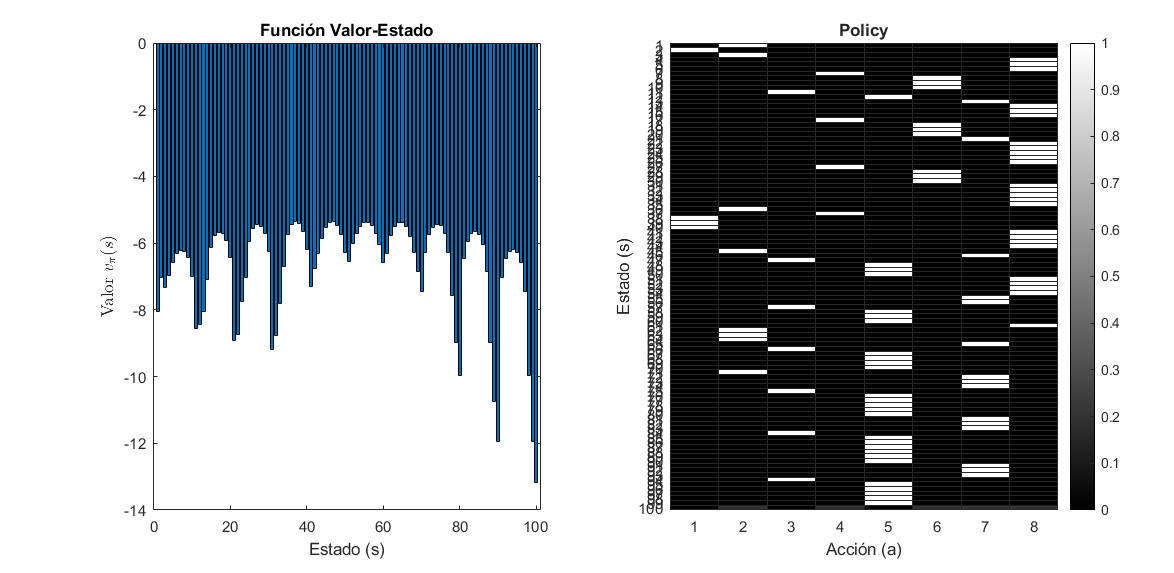

Gamma = 0.8;

% Policy Evaluation
Theta = 0.001;
Delta = 1;

% Policy evaluation
while Delta > Theta
    Delta = 0;
    q = zeros(size(Policy));
    
    for s = Estados
        V_Old = V(s);
        
        for a = Acciones
           [Recompensa,EstadoFuturo] = DinamicaGrid(a,s,MatrizEstados,EstadosMeta,EstadosObs);
           q(s,a) = (Policy(s,a) * (Recompensa + Gamma*V(EstadoFuturo)));
        end
        
        V(s) = sum(q(s,:));
        Delta = max(Delta,abs(V_Old - V(s)));
        
    end   
end

% Policy improvement
PolicyEstable = 1;

for s = Estados
    qMax = max(q(s,:));
    AccionesOptimas = find(q(s,:) == qMax);
    
    Policy(s,:) = 0;
    Policy(s,AccionesOptimas) = 1 / numel(AccionesOptimas);
end

% Gráfica de la función de valor y la policy
figure(2); clf;
PlotStateSpace(Estados,Acciones,Policy,V);

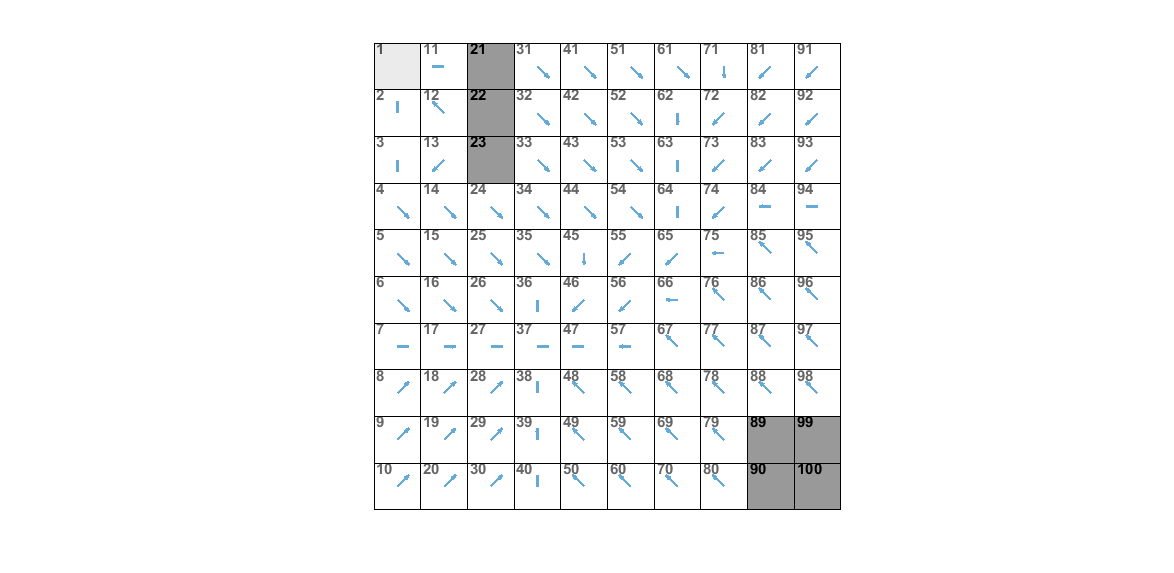

NombreAcciones = ["↑" "↓" "←" "→" "↖" "↗" "↙" "↘"];
Direcciones = [   0  0.5    % Arriba
                  0 -0.5    % Abajo
               -0.5    0    % Izquierda
                0.5    0    % Derecha
               -0.5  0.5    % Arriba-izquierda
                0.5  0.5    % Arriba-derecha
               -0.5 -0.5    % Abajo-izquierda
                0.5 -0.5];  % Abajo-derecha
DireccionesValidas = zeros(NoEstados,2);
            
for s = Estados
    AccionesValidas = find(Policy(s,:) ~= 0);
    DireccionesValidas(s,:) = Direcciones(AccionesValidas(1),:) / 2;
    if ismember(s,EstadosMeta) || ismember(s,EstadosObs)
        DireccionesValidas(s,:) = 0;
    end
end

% Componentes de Quivers
CompX = reshape(DireccionesValidas(:,1),[AltoGrid AnchoGrid]);
CompX = flipud(CompX);
CompY = reshape(DireccionesValidas(:,2),[AltoGrid AnchoGrid]);
CompY = flipud(CompY);

% Posiciones del origen del Quiver
X = 1:AnchoGrid;
Y = 1:AltoGrid;
[MeshX, MeshY] = meshgrid(X,Y);
MeshX = MeshX + 0.5;
MeshY = MeshY + 0.5;

% Color de cuadrícula
Cuadricula = ones(size(Estados));
Cuadricula(EstadosMeta) = 0.8;
Cuadricula(EstadosObs) = 0;
Cuadricula = reshape(Cuadricula,[AltoGrid AnchoGrid]);
Cuadricula = flipud(Cuadricula);
Cuadricula = [Cuadricula zeros(AltoGrid,1)];
Cuadricula = [Cuadricula; zeros(1,AnchoGrid+1)];

figure(3); clf; hold on;
quiver(MeshX,MeshY,CompX,CompY,0,'LineWidth',1.5,'MaxHeadSize',10);
surface(Cuadricula,'FaceAlpha',0.4);

% "Nombre" de estado
Num = 1;
for i = X
    for j = AltoGrid:-1:1
        text(i+0.05,j+0.9,num2str(Num),'FontWeight',"bold");
        Num = Num + 1;
    end
end
axis equal; axis off;

## Prueba de Dinámica de Grid

for a = Acciones
    [R,Sprim] = DinamicaGrid(a,6,MatrizEstados,EstadosMeta,EstadosObs)
end

R = -1

Sprim = 5

R = -1

Sprim = 7

R = -1

Sprim = 2

R = -1

Sprim = 10

R = 0

Sprim = 1

R = -1

Sprim = 9

R = -1

Sprim = 3

R = -1

Sprim = 11

## Gráficas (Función Valor-Estado / Probabilidad Estado-Acción)

function [] = PlotStateSpace(Estados,Acciones,Policy,V)
    figure('Position', [100, 100, 1024, 500]); clf; grid on;
    
    % Plot de Valor-Estado
    subplot(1,2,1);
    bar(Estados,V);
    xlabel("Estado (s)"); ylabel("Valor $v_{\pi}(s)$",'Interpreter',"latex");
    title("Función Valor-Estado")
    
    % Plot de probabilidad estado-acción
    subplot(1,2,2);
    heatmap(Acciones,Estados,Policy,'Colormap',colormap('gray'));
    xlabel("Acción (a)"); ylabel("Estado (s)"); title("Policy");
end

## Dinámica de Sistema

Función que a partir del estado meta, estado actual y acción actual (En conjunto con la matriz que representa de manera gráfica la distribución de estados en la forma de una cuadrícula), calcula la recompensa a entregar al agente, así como su estado futuro.

function [Recompensa,EstadoFuturo] = DinamicaGrid(Accion,EstadoActual,MatrizEstados,EstadosMeta,EstadosObs)
    
    % Extracción del ancho y alto del Grid
    [AltoGrid, AnchoGrid] = size(MatrizEstados);

    % Se asume inicialmente que no existirán colisiones
    ColisionBorde = 0;
    
    % Se extraen las "coordenadas" del estado actual
    [FilaActual,ColumnaActual] = find(MatrizEstados == EstadoActual);
    
    switch Accion
        % Arriba
        case 1
            EstadoFuturo = EstadoActual - 1;
            if FilaActual == 1
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar
            end
        
        % Abajo
        case 2
            EstadoFuturo = EstadoActual + 1;
            if FilaActual == AltoGrid
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
            
        % Izquierda
        case 3
            EstadoFuturo = EstadoActual - AltoGrid;
            if ColumnaActual == 1
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
        
        % Derecha
        case 4
            EstadoFuturo = EstadoActual + AltoGrid;
            if ColumnaActual == AnchoGrid
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
        
        % Arriba-izquierda
        case 5
            EstadoFuturo = EstadoActual - (AltoGrid + 1);
            if (FilaActual == 1 || ColumnaActual == 1)
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
            
        % Arriba-derecha
        case 6
            EstadoFuturo = EstadoActual + (AltoGrid - 1);
            if (FilaActual == 1 || ColumnaActual == AnchoGrid)
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
            
        % Abajo-izquierda
        case 7
            EstadoFuturo = EstadoActual - (AltoGrid - 1);
            if (FilaActual == AltoGrid || ColumnaActual == 1)
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
        
        % Abajo-derecha
        case 8
            EstadoFuturo = EstadoActual + (AltoGrid + 1);
            if (FilaActual == AltoGrid || ColumnaActual == AnchoGrid)
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
    end
    
    % Si "Estado futuro" no consiste de un "Estado meta" el agente recibe una
    % recompensa de -1. Si ya ha llegado a la meta recibe una recompensa de
    % 0.
    if isempty(find(EstadoFuturo == EstadosMeta,1))
        Recompensa = -1;
    else
        Recompensa = 3;
    end
    
    % Si el estado futuro consiste de un "Estado obstáculo" el agente
    % recibe una recompensa de -5.
    if ismember(EstadoFuturo,EstadosObs)
        Recompensa = -5;
    end
    
    % Si el agente choca con un borde recibe una recompensa de -2 (A menos
    % que dicho estado consista de un estado meta).
    if (ColisionBorde == 1 && Recompensa ~= 0)
        Recompensa = -2;
    end
    
end